# **Das Spiel des Lebens**

## **Die Spielregeln**

Die Folgegeneration wird für alle Zellen gleichzeitig berechnet und ersetzt die aktuelle Generation. Der Zustand einer Zelle (*lebendig* oder *tot*) in der Folgegeneration hängt nur vom aktuellen Zustand der Zelle selbst und den aktuellen Zuständen ihrer Nachbarzellen ab. 

Die von Conway zu Anfang verwendeten Regeln sind:  

- Eine tote Zelle mit genau drei lebenden Nachbarn wird in der Folgegeneration neu geboren.

- Lebende Zellen mit weniger als zwei lebenden Nachbarn sterben in der Folgegeneration an Einsamkeit.

- Eine lebende Zelle mit zwei oder drei lebenden Nachbarn bleibt in der Folgegeneration am Leben.

- Lebende Zellen mit mehr als drei lebenden Nachbarn sterben in der Folgegeneration an Überbevölkerung.

Mit diesen vier einfachen Regeln entsteht aus bestimmten Anfangsmustern im Laufe des Spiels eine Vielfalt komplexer Strukturen. Einige bleiben unverändert, andere oszillieren und wieder andere wachsen oder vergehen. Manche Strukturen, sogenannte *Gleiter*, bewegen sich auf dem Spielfeld fort. Sogar logische Funktionen wie UND und ODER lassen sich durch bestimmte Anfangsmuster simulieren. Damit können dann sogar komplexe Funktionen der Schaltungslogik und digitalen Rechnertechnik nachgebaut werden.

## 1) Vorbereitung

Lesen Sie sich das Arbeitsblatt durch und füllen Sie es aus.

## 2) Implementierung

Erstellen Sie ein Lauffähiges Programm für das Spiel des Lebens mit den vorgestellten Spielregeln in der letzten Codebox dieses FIles. Rufen Sie es anschließend mit folgender initialen Einstellung auf.

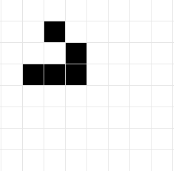

%n=...;

n= 10

n = 10

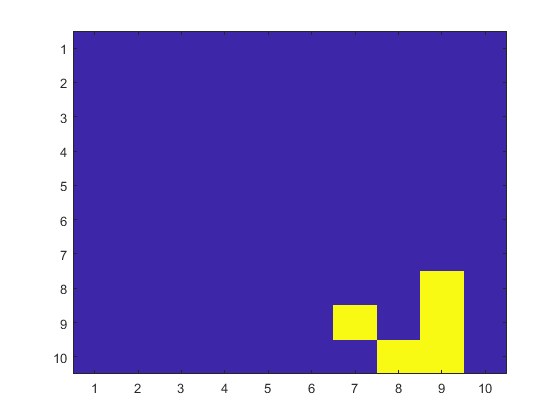

A=zeros(n);
A(1:4,1:4)=[0,0,0,0;0,0,1,0;0,0,0,1;0,1,1,1];

GoL(A,n);

Dieses Muster sollte sich periodisch wiederholen und durchs Bild gleiten. Auf diese Weise können Sie auch kontrollieren ob Ihre Randbedingung funktionieren. Der Celluläre Automat kann mit Hilfe von *imagesc* und *pause* in eine Animation verwandelt werden.

## 3) Case Study

Ihre Aufgabe umfasst nun 3 unterschiedliche Ausgangsstellungen zu definieren um unterschiedliche Szenarien zu erzeugen.

- Beliebiges Szenario

- Einen Gleiter

- Eine oszilierende Abfolge

### Ein beliebiges Szenario

% Definieren Sie hier Ihre Initialisierungsmatrix für ein beliebiges Scenario

n = 100
A1 = round(rand(n)) %faul, aber schöne muster!

GoL(A1,n)

### Der Gleiter

% Definieren Sie hier Ihre Initialisierungsmatrix für einen Gleiter
% Das Muster  in 2) wäre schon ein gleiter.


% Das ist zwar kein gleiter, aber es erzeugt welche!
% Gosper glider gun


gun_raw = ['........................O...........'
'......................O.O...........'
'............OO......OO............OO'
'...........O...O....OO............OO'
'OO........O.....O...OO..............'
'OO........O...O.OO....O.O...........'
'..........O.....O.......O...........'
'...........O...O....................'
'............OO......................'];
gun = gun_raw == 'O';

n = 100

A2 = zeros(n);
A2(11:19,11:46) = gun;


GoL(A2,n)


### Oszillierendes Verhalten

% Definieren Sie hier Ihre Initialisierungsmatrix für oszillierendes
% Verhalten des Automata
 
n = 5
A4 = zeros(n)
A4(2:4,3) =1
GoL(A4,n)

### Algorithmus für GameofLife

Sie können hier auch nested MATLAB-Functions verwenden indem Sie diese nach der Hauptfunktion definieren.

%% Schreiben Sie eine MATLAB Funktion die das GameOfLife wiederspiegelt.

% Parameter des Programms
% n     Dimension des Spielfeldes
% A     Initialisierungsmatrix
%

%%

function [Animation] = GoL(A,n)
    imagesc(A)
    current_A = A;
% animated gif von jörg

%     % fuer gif:
%     bild = figure;
%     filename = 'zzgifCA.gif';
%     frame = getframe(bild);
%     im = frame2im(frame);
%     [imind,cm] = rgb2ind(im,256);
%     imwrite(imind,cm,filename,'gif', 'Loopcount',1,'DelayTime',0.3);



    max_iterations = 10000;
    for counter = 1:max_iterations
        new_A = zeros(n);
        for i = 1:n
            for j = 1:n
                
                % select 9 relevant tiles:
                idx1 = [-1,0,1]+i;
                idx2 = [-1,0,1]+j;
                
                % on Torus, outsides of matrix are identified with other sides
                % (I've also seen versions where they are simply presumed
                % dead?)
                idx1(idx1<1) = n;
                idx1(idx1>n) = 1;
                idx2(idx2<1) = n;
                idx2(idx2>n) = 1;
                submatrix = current_A(idx1,idx2);
                
                if current_A(i,j) == 1
        
                
                    n_living_neighbors = sum(submatrix,'all') -1;
                    % we know that in this if condition the center is 1 as well
                    % so one too many
                    if n_living_neighbors < 2 || n_living_neighbors > 3
                        new_A(i,j) = 0;
                    else
                        new_A(i,j) = 1;
                    end
                
                else
                            
                    n_living_neighbors = sum(submatrix,'all');
                    % same as above, but without the - 1 because center is 0
                    % anyways
                    
                    if n_living_neighbors==3
                        new_A(i,j) = 1;
                    else
                        new_A(i,j) = 0;
                    end
                end
                            
            end
            
        end
        

%         if ((isequal(A,current_A)) && (counter ~= 1))
%             'Eine Periode durchlaufen!'
%             pause(0.5)
%         end
%         if mod(counter,100) == 0
%             'another 100 iterations done'
%             end
%         

        current_A = new_A;
        imagesc(current_A)
        pause(0.05)

%% für gifs 2. teil

%         frame = getframe(bild);
%         im = frame2im(frame);
%         [imind,cm] = rgb2ind(im,256);
%         imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',0.05);
    end
end
    


